# **디지털신호처리 ****HW#1**

Due date : 2021.10.21. 23:59

**이름**** : 채경태    **

**학번**** : 201716330**

아래 문제에 대하여 MATLAB으로 구현하고 mlx파일을 본인의 Github에 업로드 하고 링크 주소를 적으세요.

**Repository 링크 : https://github.com/201716330/tasks.git**

1. 다음 신호를 stem 함수를 이용하여 그려라.

1) 

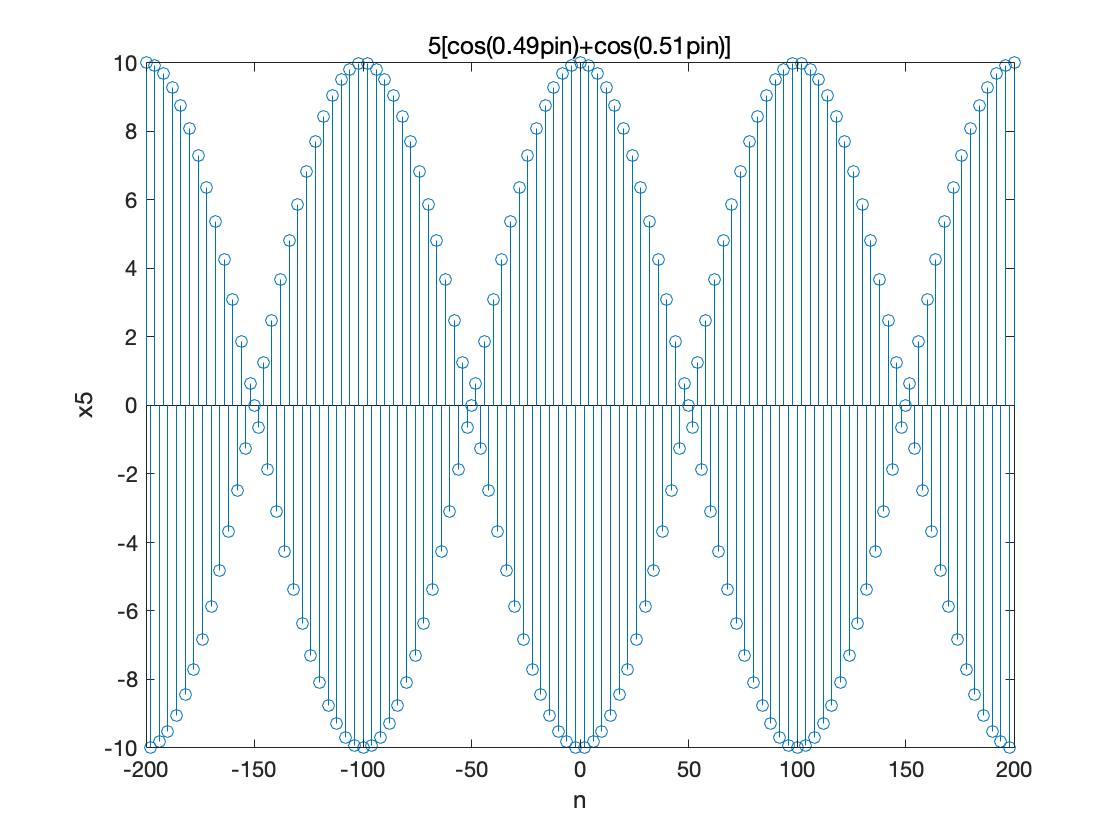

n = -200:2:200;
X5 = 5*(cos(0.49*pi*n) + cos(0.51*pi*n));
stem(n,X5);
title('5[cos(0.49pin)+cos(0.51pin)]');
xlabel('n'); ylabel('x5');

2) 

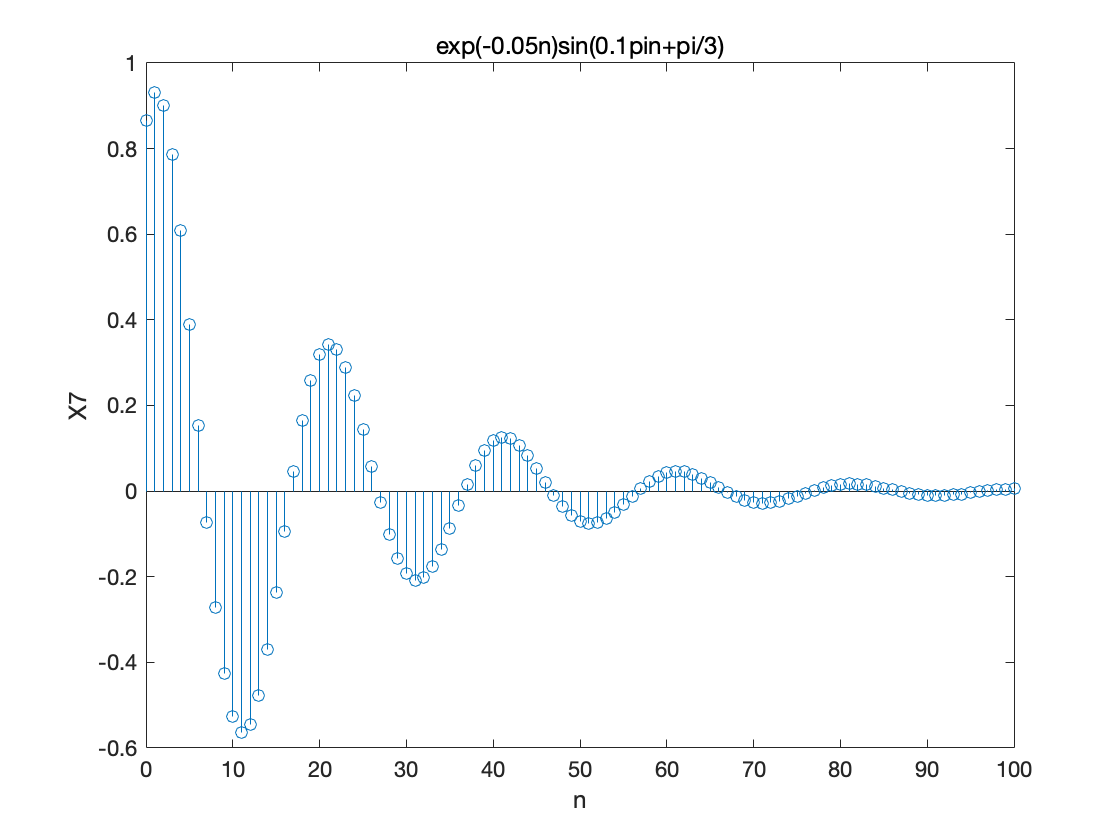

n = 0:100;
X7 = exp(-0.05*n).*sin(0.1*pi*n + pi/3);
stem(n,X7);
title('exp(-0.05n)sin(0.1pin+pi/3)');
xlabel('n'); ylabel('X7');

2.  (P2.16) LTI 시스템의 차분 방정식이 다음과 같다.


$$y\left(n\right)-0\ldotp 5y\left(n-1\right)+0\ldotp 25y\left(n-2\right)=x\left(n\right)+2x\left(n-1\right)+x\left(n-3\right)$$


1) MATLAB의 impz 함수를 사용하여 0<=n<=100 구간에서 시스템의 임펄스 응답을 구하고 stem을 이용해서 그려라.

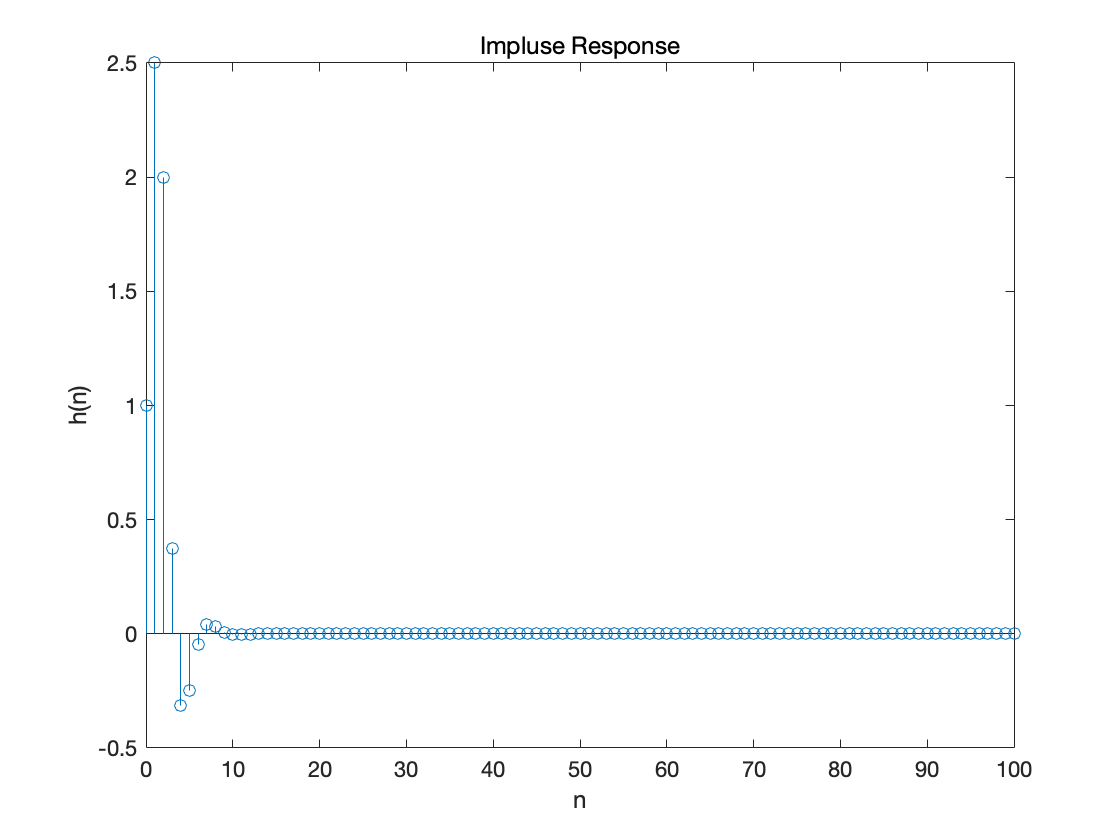

b = [1, 2, 1];
a = [1, -0.5, 0.25];
n = [0:100];
h = impz(b,a,n);
stem(n,h);
title('Impluse Response'); xlabel('n'); ylabel('h(n)')

2) 이 임펄스 응답으로부터 안정성을 판별하라. (sum, abs 함수 사용)

sum(abs(h))

ans = 6.5714

%ans = 6.5714는 시스템이 안정함을 보여준다.

3) 만약 이 시스템의 입력이$x\left(n\right)=\left\lbrack 5+3\cos \left(0\ldotp 2\pi n\right)+4\sin \left(0\ldotp 6\pi n\right)\right\rbrack u\left(n\right)$이면, filter 함수를 사용하여0<=n<=200 구간에서 응답 y(n)을 구하라.

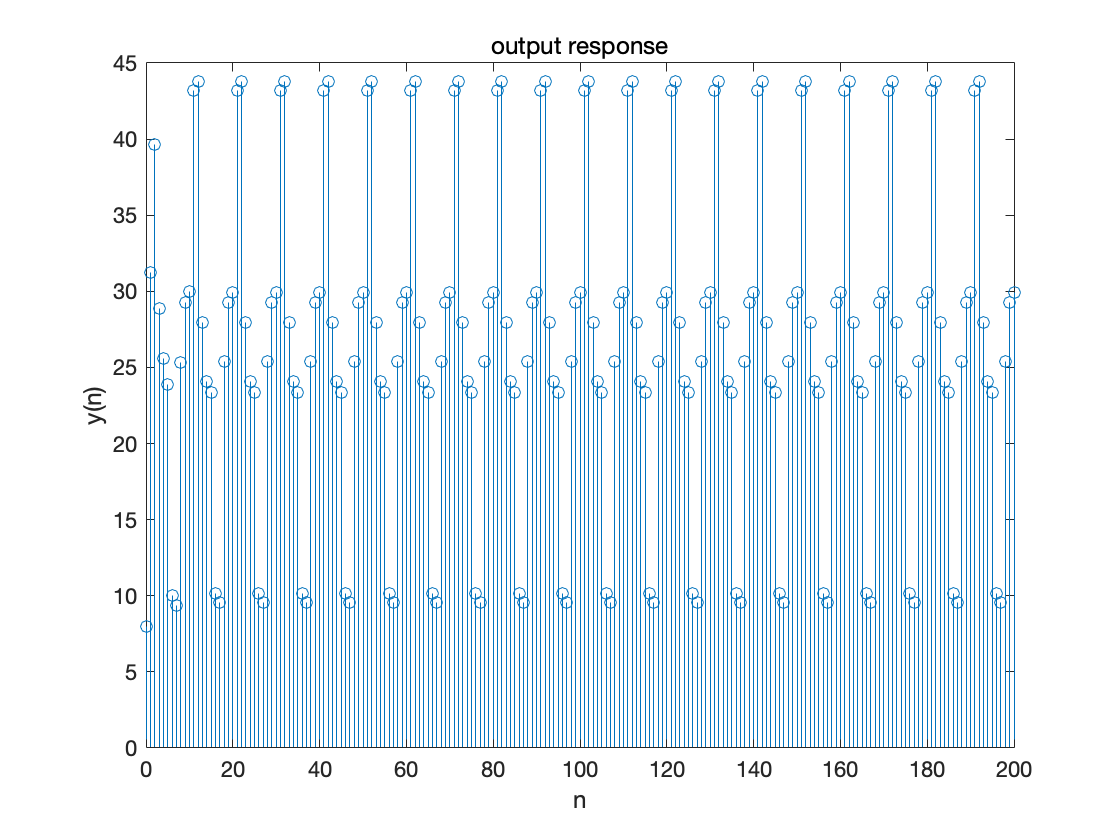

b = [1, 2, 0, 1 ];
a = [1 ,-0.5,0.25]; 
n = 0:200;
x = 5*ones(size(n))+3*cos(0.2*pi*n)+4*sin(0.6*pi*n);
y = filter(b,a,x);
Hs = stem(n,y);
title('using filter function');
xlabel('n'); ylabel('y(n)')

3. (P2.20) 

일 때, 다음을 그려라. 

1) y(n)의 처음 51개 샘플을 stem 함수 이용해서 그려라. 

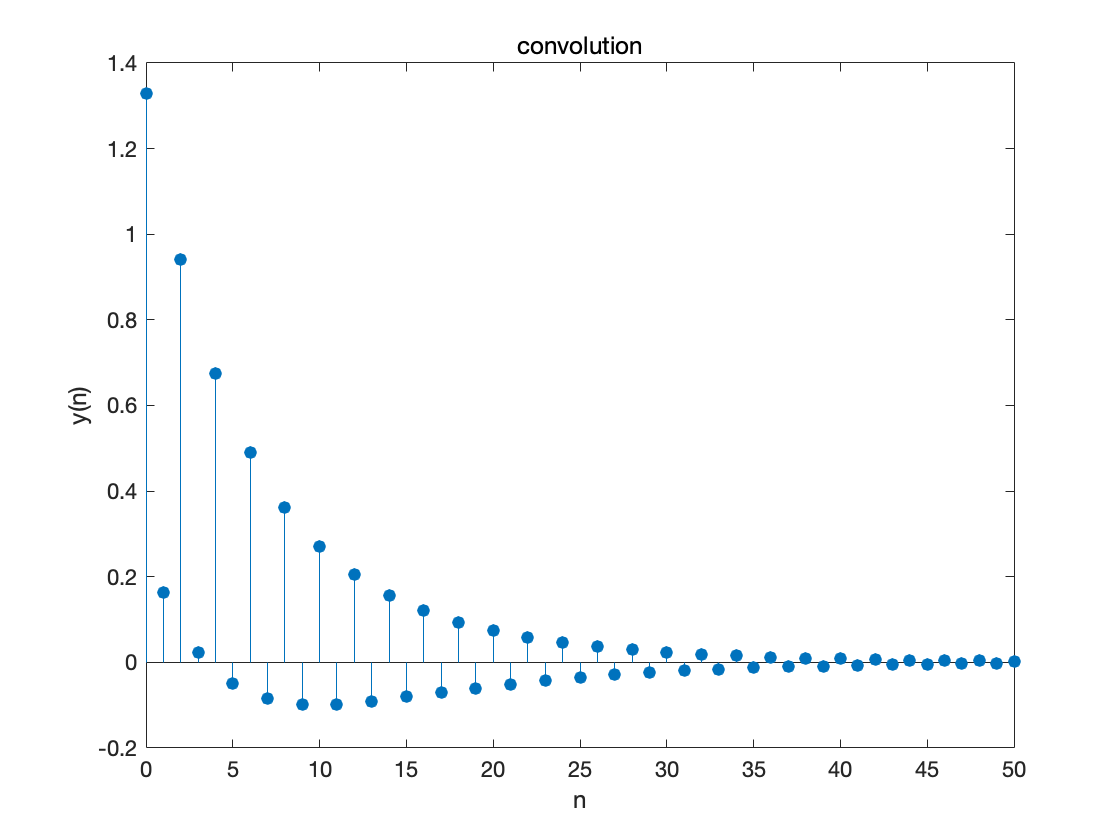

n = 0:50;
x = (0.8).^n;
h = (-0.9).^n;
y1 = ((0.8).^(n+1) - (-0.9).^(n+1)/ (0.8+0.9));
Hs1 = stem(n,y1);
title('convolution');
xlabel('n'); ylabel('y(n)');

2) x(n)과 h(n)을 26개의 샘플이 되도록 자른뒤, conv 함수를 이용해서 y(n)을 구하고 stem 이용해서 그려라. 

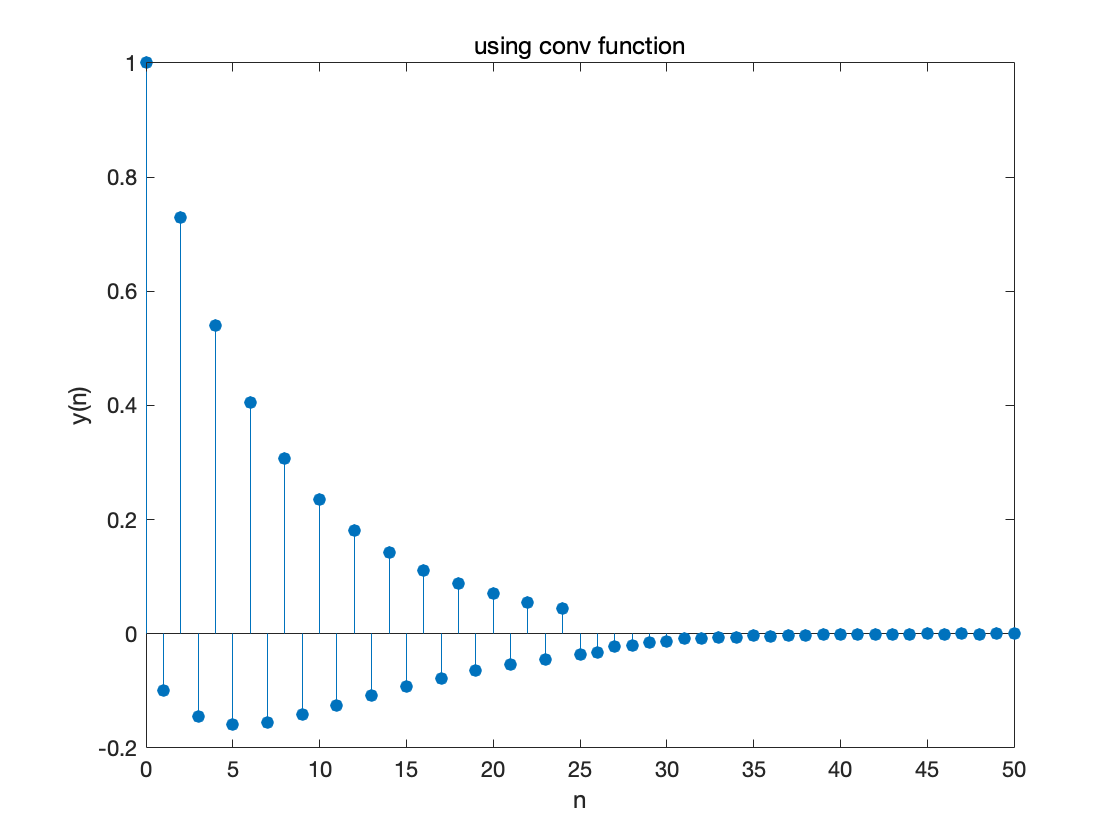

x2 = x(1:26); h2 = h(1:26); y2 = conv(h2,x2);
Hs2 = stem(n,y2);
title('using conv function'); 
xlabel('n'); ylabel('y(n)');

3) filter 함수를 이용해서 $x\left(n\right)\ast h\left(n\right)$의 처음 51개 샘플을 구하고 stem 이용해서 그려라. 

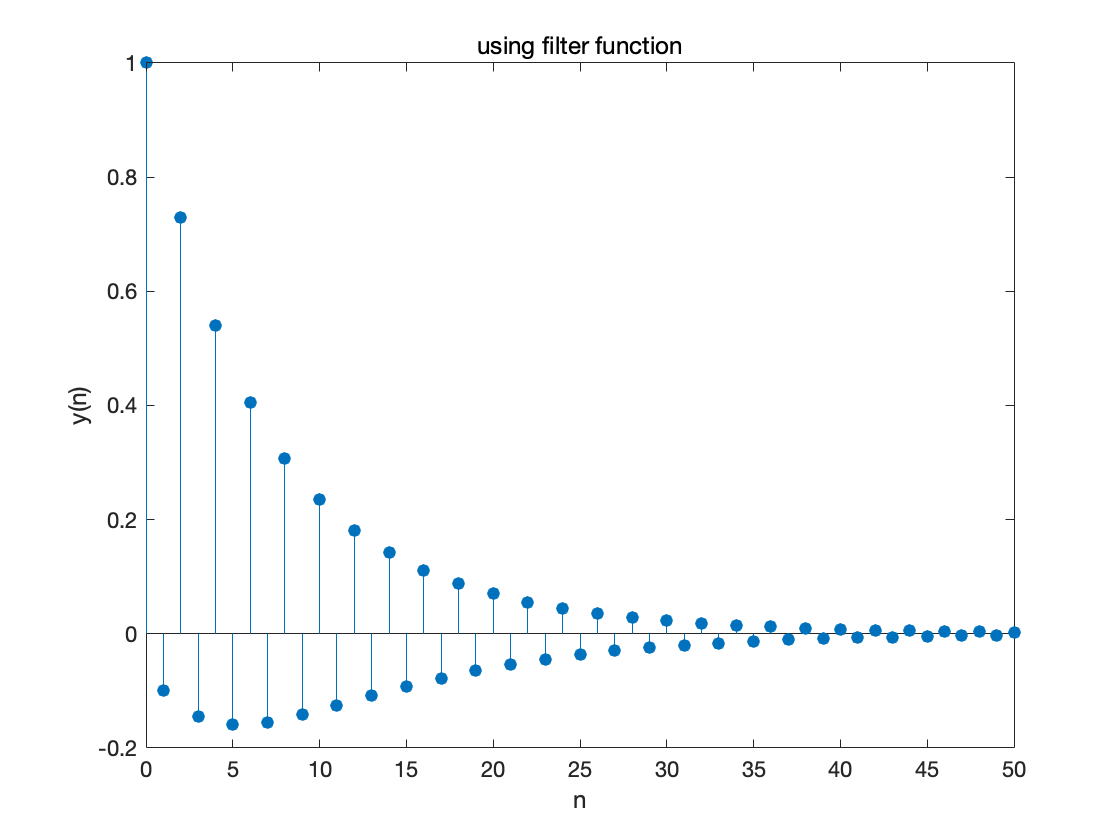

y3 = filter([1],[1,0.9],x);
Hs3 = stem(n,y3);
title('using filter function')
xlabel('n'); ylabel('y(n)');

4. (P3.14) 임펄스 응답으로 기술된 각 선형 시불변 시스템에 대해 구간 $\left\lbrack -\pi ,\pi \right\rbrack$에서 주파수 응답 함수 $H\left(e^{j\omega } \right)$을 구하고 크기 응답과 위상 응답을 그려라. 

1) $h\left(n\right)={\left(0\ldotp 9\right)}^{|n|}$


$$H\left(e^{\textrm{jw}} \right)=\frac{1}{1-0\ldotp 9e^{\textrm{jw}} }+\frac{1}{1-0\ldotp 9e^{-\textrm{jw}} }-1=\frac{0\ldotp 19}{1\ldotp 81-1\ldotp 8\cos \left(w\right)\;}$$


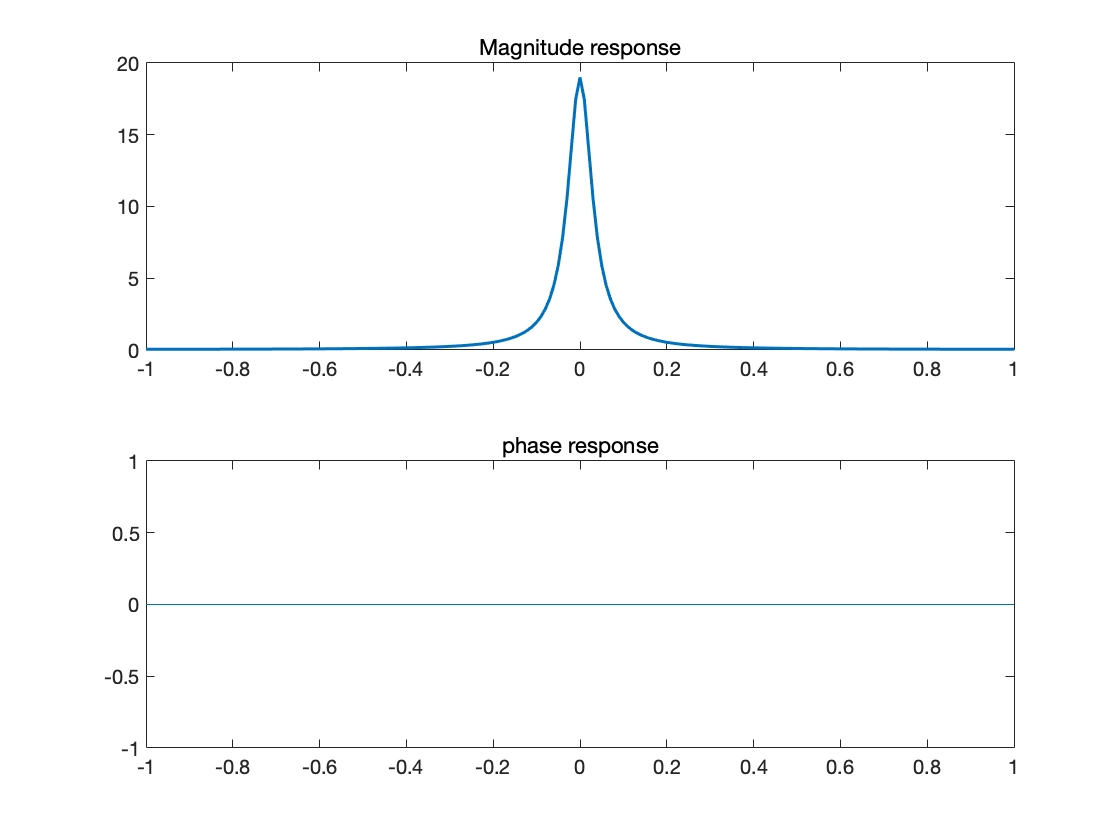

w = [-100:100]*pi/100;
H = 0.19*ones(size(w))./(1.81-1.8*cos(w));

magH = abs(H);
phaH = angle(H)*180/pi;

subplot(2,1,1); plot(w/pi,magH,'LineWidth',1.5); axis([-1 1 0 20]);
title('Magnitude response');
subplot(2,1,2); plot(w/pi,phaH);
title('phase response');

2) $h\left(n\right)=\left\lbrack {\left(0\ldotp 5\right)}^n +{\left(0\ldotp 4\right)}^n \right\rbrack u\left(n\right)$


$$H\left(e^{\textrm{jw}} \right)=$$
 
$$\frac{1}{1-0\ldotp 5e^{-\textrm{jw}} }+\frac{1}{1-0\ldotp 4e^{-\textrm{jw}} }=\frac{2-0\ldotp 9e^{-\textrm{jw}} }{1-0\ldotp 9e^{-\textrm{jw}} +0\ldotp 2e^{-2\textrm{jw}} }$$


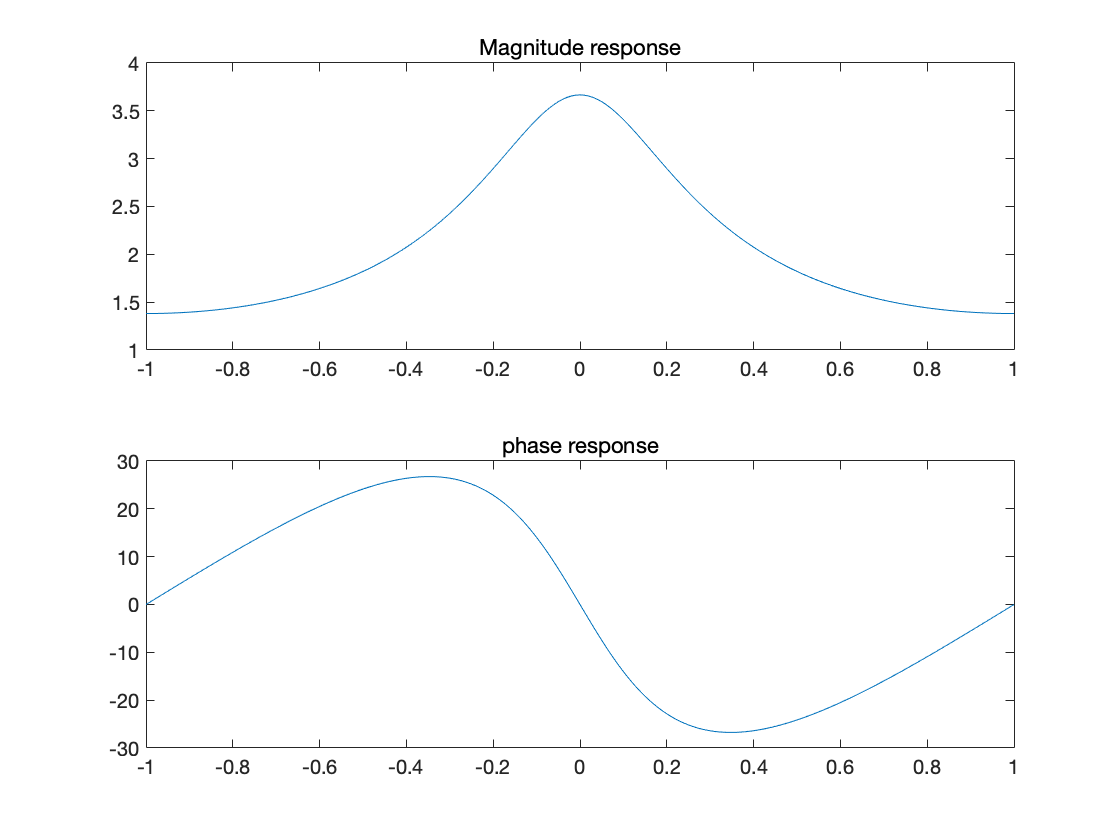

n = -pi : pi;
w = [-100:100]*pi/100 ; 
H = (2-0.9*exp(-j*w))./(1-0.9*exp(-j*w)+0.2*exp(-j*2*w));

magH = abs(H);
phaH = angle(H)*180/pi;

subplot(2,1,1); plot(w/pi,magH);
title('Magnitude response');

subplot(2,1,2); plot(w/pi,phaH);
title('phase response');

6. (P3.19) 다음의 각 시스템에 대해 $H\left(e^{j\omega } \right)$을 구하고, 그 크기와 위상을 그려라

1) $y\left(n\right)=x\left(n\right)-x\left(n-2\right)+0\ldotp 95y\left(n-1\right)-0\ldotp 9025y\left(n-2\right)$

2) $y\left(n\right)=x\left(n\right)-\sum_{l=1}^5 {\left(0\ldotp 5\right)}^n y\left(n-l\right)$

5. (P3.17) 

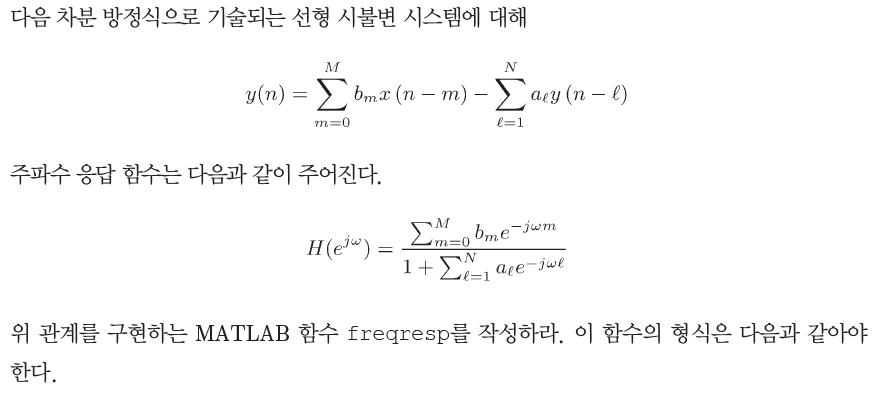

function [H] = freqresp(b,a,w)

H = num./den
end